# Sample file for using the Balanced Partition (BP) domain

%% Cleanup
clc
clear
close all


## Load required packages:

addpath('..\src\'); % Adds current folder
addpath(genpath('extended\Domains')); % Adds all domains functionality
addpath(genpath('extended\Utils')); % Adds assorted utilities


## Load BP Instances:

trainingInstances = BP.loadInstanceSet('rand5E8B');


## Create basic HH:

HHParams = struct('targetProblemHandle',@BP,'nbRules',3,'selectedFeatures',1,'selectedSolvers',1:2);
HH1 = ruleBasedSelectionHH(HHParams);
disp(HH1)

Displaying information about the New HH:
	Target problem:      BP
	Type:                Rule-based
Training information:
	Method:     Undefined
	Number of instances: 0 (training) | 0 (testing)
	Parameters:
   NaN

	Performance achieved:	
	Time taken:	NaN
	Evaluations taken:	NaN
	Iterations performed:	NaN
	Status of stop criteria:
   NaN

Model-specific information:
	Number of rules:	3
	Usable features:	1 (  1  )
	Usable solvers:	2 (  1  2  )
	Current model:
    0.6963    2.0000
    0.6607    2.0000
    0.2422    2.0000



HH2 = ruleBasedSelectionHH(HHParams);
disp(HH2)

Displaying information about the New HH:
	Target problem:      BP
	Type:                Rule-based
Training information:
	Method:     Undefined
	Number of instances: 0 (training) | 0 (testing)
	Parameters:
   NaN

	Performance achieved:	
	Time taken:	NaN
	Evaluations taken:	NaN
	Iterations performed:	NaN
	Status of stop criteria:
   NaN

Model-specific information:
	Number of rules:	3
	Usable features:	1 (  1  )
	Usable solvers:	2 (  1  2  )
	Current model:
    0.4154    1.0000
    0.8111    2.0000
    0.2489    2.0000



## Enforce a model

newModel = [1 1; 0.5 2];
HH2.setModel(newModel);
disp(HH2)

Displaying information about the New HH:
	Target problem:      BP
	Type:                Rule-based
Training information:
	Method:     Undefined
	Number of instances: 0 (training) | 0 (testing)
	Parameters:
   NaN

	Performance achieved:	
	Time taken:	NaN
	Evaluations taken:	NaN
	Iterations performed:	NaN
	Status of stop criteria:
   NaN

Model-specific information:
	Number of rules:	2
	Usable features:	1 (  1  )
	Usable solvers:	2 (  1  2  )
	Current model:
    1.0000    1.0000
    0.5000    2.0000



## Train

HH1.trainingInstances = trainingInstances;
trainParams = struct('maxIter',50);
HH1.train('UPSO',trainParams)


[  09:03:35] UPSO2 starts...
         ... Inputs and outputs checked!
         ... Parameters initialised:

           visualMode: 0
          verboseMode: 1
       populationSize: 15
              maxIter: 50
          maxStagIter: 50
             selfConf: 2
           globalConf: 2.5000
          unifyFactor: 0.2500
      numberVariables: 6
    simpleConstraints: 1
             knownMin: -Inf
              stagTol: 0.1000
              funcTol: 1.0000e-03
               solTol: 1.0000e-06
         fitnessLimit: 1.0000e-06
          kappaFactor: 1
            phiFactor: 4.5000
       initialVelMode: 'rand'

         ... Neighbours established
         ... Population positions randomly initialised
         ... Population velocities randomly initialised
         ... Population initialised
         ... Search space adjusted
         ... Particular best fitness values determined

[Step     1] Global best fitness updated: 1388
         ... Initialisation completed!

[Step     2] Global b

ans =     0.0442
    0.8787
    0.6775
    1.0320
    1.0608
    1.6956


disp(HH1)

Displaying information about the Trained HH:
	Target problem:      BP
	Type:                Rule-based
Training information:
	Method:     UPSO
	Number of instances: 10 (training) | 0 (testing)
	Parameters:
        visualMode: 0
       verboseMode: 1
    populationSize: 15
           maxIter: 50
       maxStagIter: 50
          selfConf: 2
        globalConf: 2.5000
       unifyFactor: 0.2500

	Performance achieved:	1388.00
	Time taken:	56.45
	Evaluations taken:	800
	Iterations performed:	50
	Status of stop criteria:
       iterationFlag: 1
    fitnessLimitFlag: 0
      stagWindowFlag: 0
        stagStatFlag: 0

Model-specific information:
	Number of rules:	3
	Usable features:	1 (  1  )
	Usable solvers:	2 (  1  2  )
	Current model:
    0.0442    1.0000
    0.8787    1.0000
    0.6775    2.0000



## Calculate Oracle

HH1.getOracle(trainingInstances);
disp(HH1.oracle)

                   isReady: 1
           lastPerformance: 146
     lastInstanceSolutions: [10×1 double]
           lastBestSolvers: [10×1 double]
            lastHeuristics: [1 2]
    lastHeuristicSolutions: [10×2 double]
         unsolvedInstances: {10×1 cell}



## Compare against Oracle

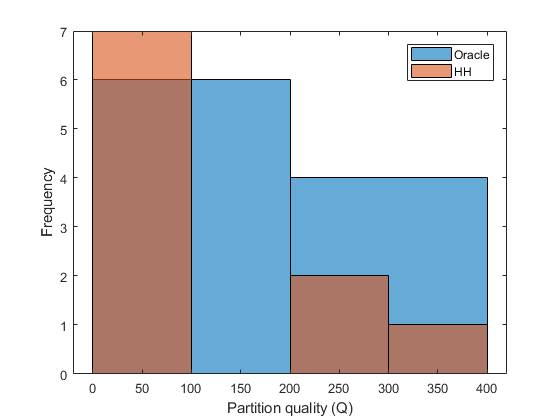

HH1.compareVsOracle(trainingInstances);

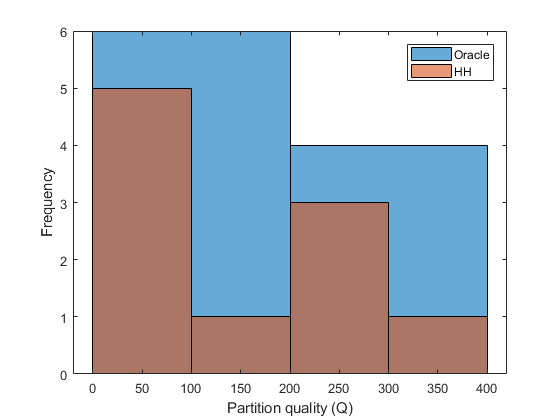

HH2.compareVsOracle(trainingInstances);

## Plot zones and rules

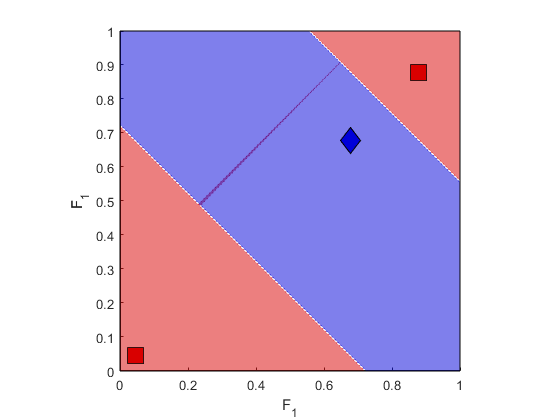

newPoints = 0:0.005:1; % Increased resolution w.r.t. default
customFeature = 1; % 
doEuclid = true;
doRules = true;
allAreas  = HH1.plotZones(newPoints,doEuclid,customFeature,doRules);

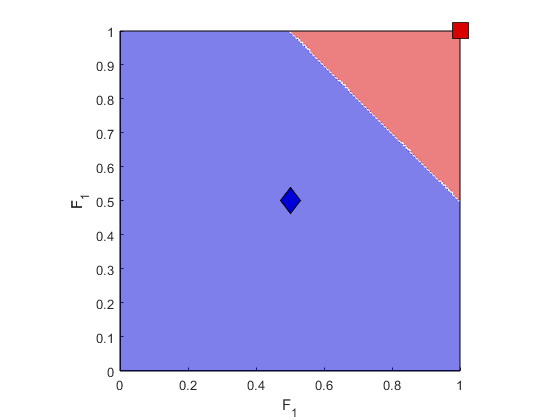

allAreas2 = HH2.plotZones(newPoints,doEuclid,customFeature,doRules);

## Feature tracker

ans =   Surface with properties:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'interp'
    FaceLighting: 'flat'
       FaceAlpha: 0.6500
           XData: [-0.1000 0.0500 0.1500 0.2500 0.3500 0.4500 0.5500 0.6500 0.7500 0.8500 0.9500 1.1000]
           YData: [-0.1000 0.0500 0.1500 0.2500 0.3500 0.4500 0.5500 0.6500 0.7500 0.8500 0.9500 1.1000]
           ZData: [12×12 double]
           CData: [12×12 double]

  Show all properties


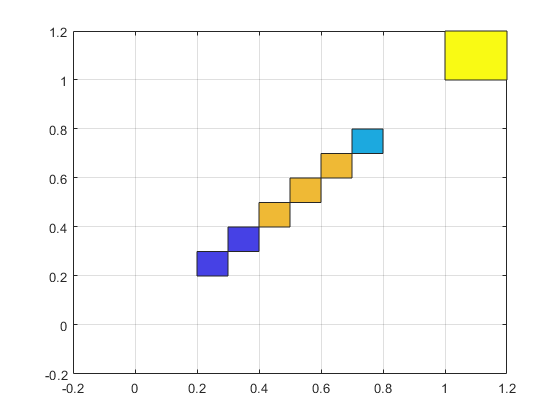

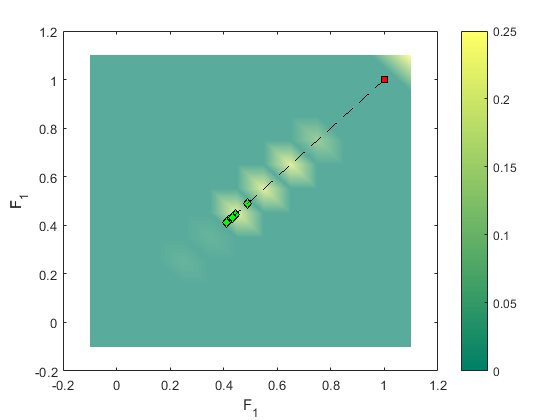

HH2.plotFeatureMap(trainingInstances,'full',struct('features',[1 1]),true,[1 2 5 7:10])